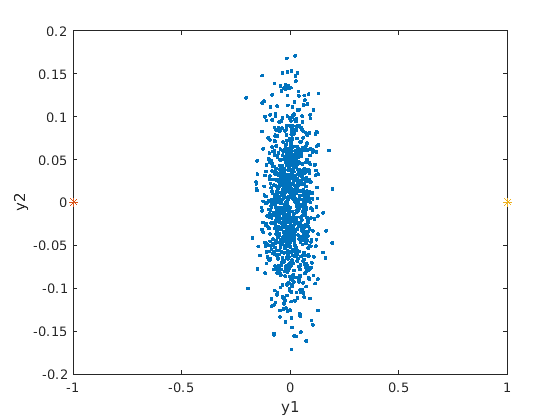

s1 = [-1, 0]';
s2 = [1, 0]';
% tolerance
tol = 25;
% Number of states
N = 1000;
% Position sequence
X = [10*(1:N) + rand(1,N); rand(1,N)];
% Random sensor position sequence
s = rand(2,1);
% Measurement noise covariance
sigma_r=pi/50;
R=diag([sigma_r sigma_r]).^2;
% Measurement model
measModel = @(X) dualBearingMeasurement(X, s1, s2);
seed = rng;
Y = genNonLinearMeasurementSequence(X, measModel, R);
rng(seed);

figure(1),clf
plot(Y(1,:),Y(2,:),'.')
hold on
plot(s1(1),s1(2),'*')
plot(s2(1),s2(2),'*')
xlabel('y1');ylabel('y2');